# EE-414 Speech Processing Lab

#  Lab-4

## Aim 

#### ● To understand the time and frequency domain characteristics of voiced and unvoiced speech. 

#### ● To perform the voiced/unvoiced/silence classification of speech. 

## Introduction:

Based on an input excitation to a system, the system will give back a response. In the speech processing domain, the system can be considered as a speech production system (the region above the glottis) and the input excitation is the air rushing out from lungs to the glottis, and this system will give back certain categories of responses. The responses produced by this system are categorized as: Voiced speech, Unvoiced speech and silence region. The voiced speech is produced when input excitation is periodic in nature (when vocal folds of glottis vibrates periodically), the unvoiced speech is produced when input excitation is aperiodic (there is obstruction/constriction to the air flow) and silence is produced when the system is given no excitation.

### A.

### Record the phrase “Speech signal” and plot the time waveform. Use 16kHz and 16 bits/sample as the sampling frequency and bit resolution respectively. 

### 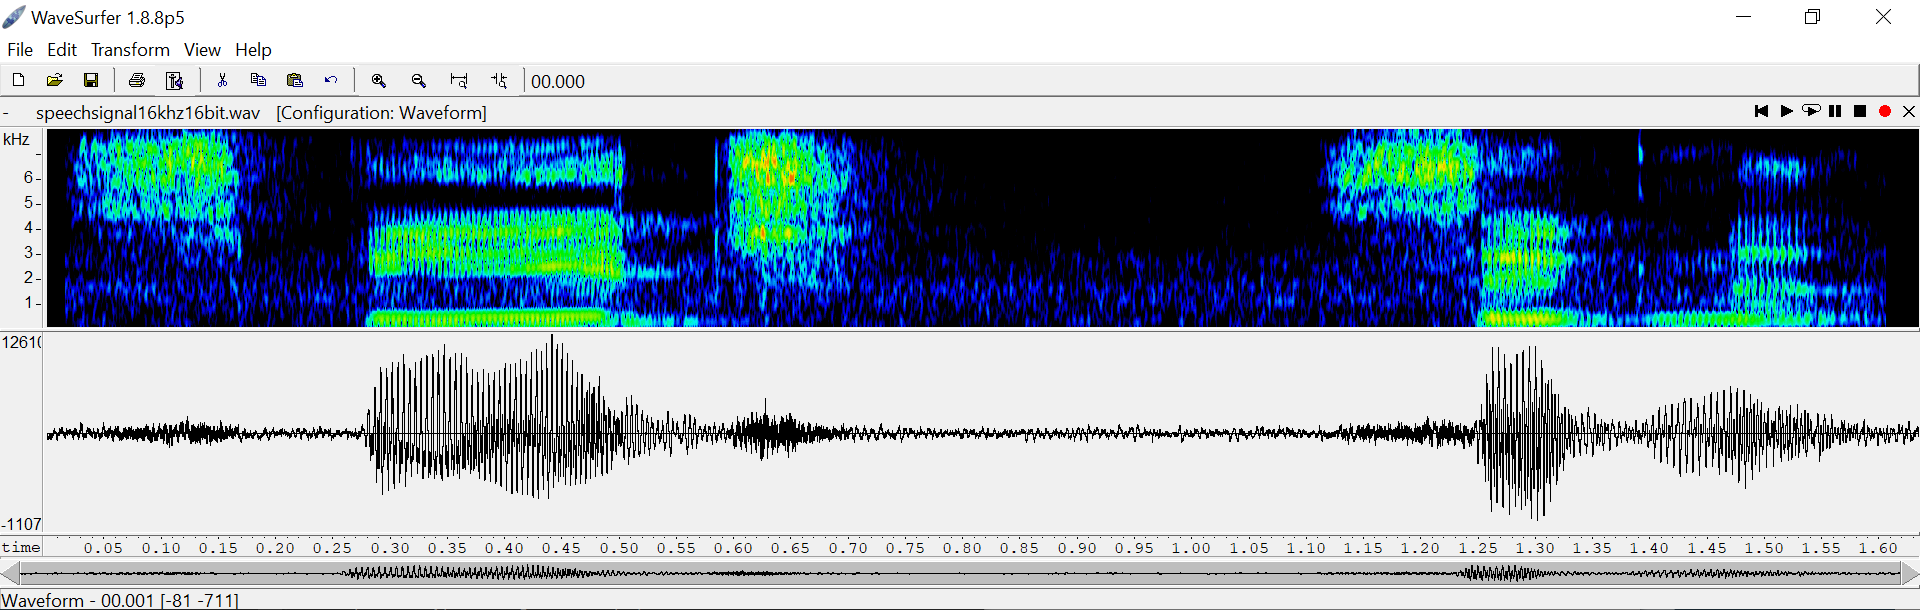

### Theory:

We need to plot the analog speech signal in digital format, which is done easily with the help of matlab. Time domain plots are necessary to see how the amplitude of the speech signal is varying with time. 

### Procedure:

We will use Audacity software to record the signal with the given requirements (by setting 16 kHz and 16 bits/sample in the software itself) to get the wave file. We then read this wave file using *audioread() *and plot its time domain signal using user defined function *plot_time_signal().*

### Code and Plots:

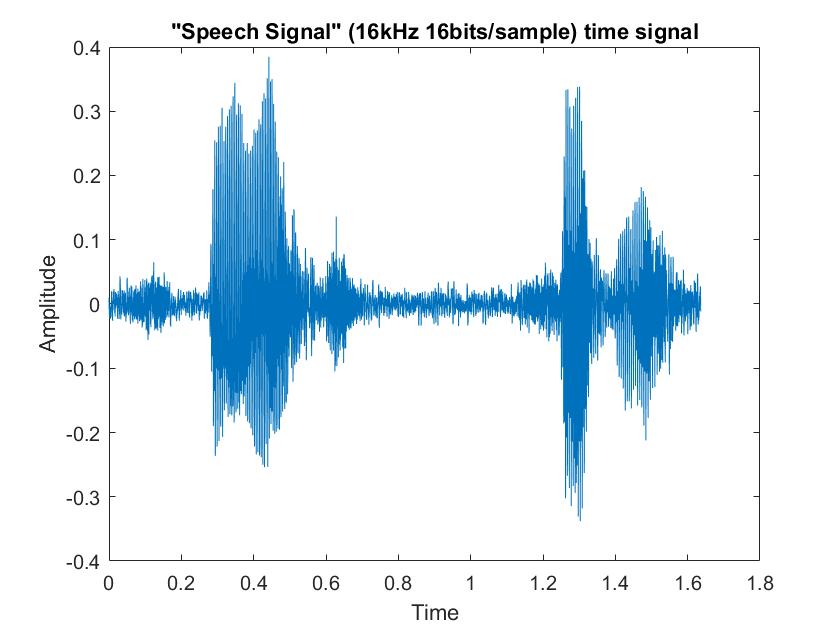

close all; clc; clear all;

[y,fs]=audioread('speechsignal16khz16bit.wav'); 
sound(y, 16000);

% "Speech Signal" 
plot_time_signal(y, fs, '"Speech Signal" (16kHz 16bits/sample) time signal'); 

### Observations:

We see that voiced speech has higher amplitudes as compared to unvoiced speech signals, and silence has the least amplitude (only consists of noise). Also voiced speech has periodic nature whereas silence and unvoiced speech is aperiodic in nature.

### B.

### Examine "s", "ch", any one vowel, any one nasal from A as follows. Take one segment of 25 ms duration at the centre of the sound. Compute and plot the Autocorrelation function, and comment on the periodicity of the sounds. Compare the autocorrelation plots for various sounds and comment on how autocorrelation can be used for classifying the sounds as voiced and unvoiced.

### Theory:

The autocorrelation function allows to compute the correlation of a signal with itself as a function of time. We multiply the corresponding samples and sum it for different delays. It is useful for finding out if a speech signal is periodic or aperiodic and computing the pitch period if it is periodic.

### Procedure:

We take different sound segments from original speech signal and plot time domain plots. We then use a user defined function *ACF(no_of_samples, signal) *to compute the autocorrelation function of a respective sound segment and then plot ACF vs delay for each sound.

### Code and Plots:

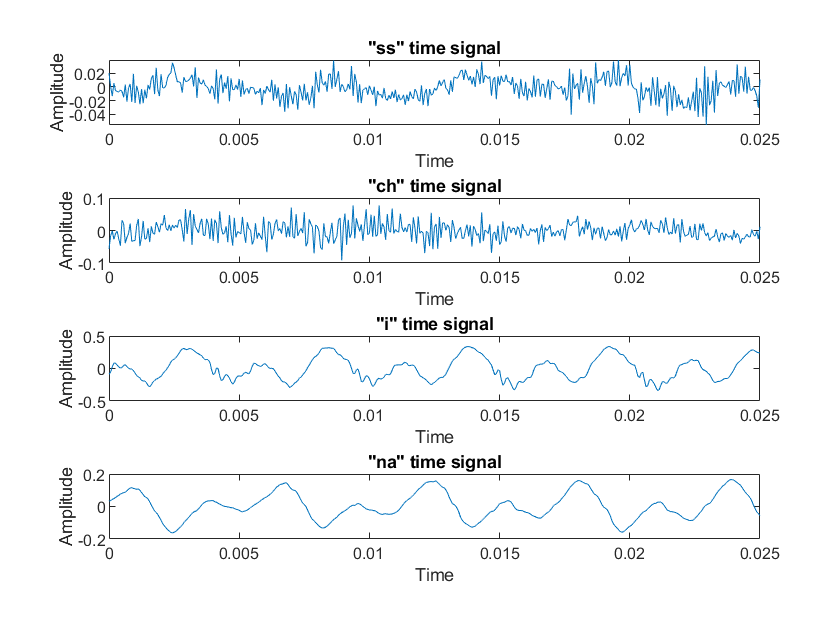

ss_sound = y(int64(0.085*fs):int64((0.085+0.025)*fs));  % fricative
ch_sound = y(int64(0.64*fs):int64((0.64+0.025)*fs));    % affricate
i_sound = y(int64(1.282*fs):int64((1.282+0.025)*fs));   % vowel
na_sound = y(int64(1.442*fs):int64((1.442+0.025)*fs));  % nasal

subplot(411);
plot_time_signal(ss_sound, fs, '"ss" time signal');
subplot(412);
plot_time_signal(ch_sound, fs, '"ch" time signal');
subplot(413);
plot_time_signal(i_sound, fs, '"i" time signal');
subplot(414);
plot_time_signal(na_sound, fs, '"na" time signal');

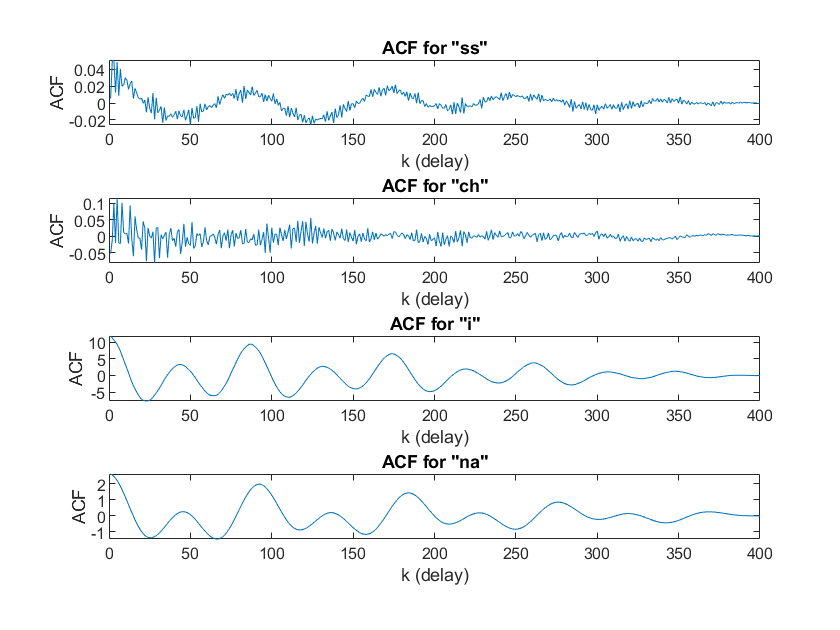

N = 0.025*16000; % no. of samples
subplot(411);
ACF = autocorr(N, ss_sound);
plot((1:N), ACF);
title('ACF for "ss"');
xlabel('k (delay)');
ylabel('ACF');

subplot(412);
ACF = autocorr(N, ch_sound);
plot((1:N), ACF);
title('ACF for "ch"');
xlabel('k (delay)');
ylabel('ACF');

subplot(413);
ACF = autocorr(N, i_sound);
plot((1:N), ACF);
title('ACF for "i"');
xlabel('k (delay)');
ylabel('ACF');

subplot(414);
ACF = autocorr(N, na_sound);
plot((1:N), ACF);
title('ACF for "na"');
xlabel('k (delay)');
ylabel('ACF');

### Observations:

We can see distinct peaks in the case for voiced speech easily whereas for unvoiced speech we cant uniquely distinguish the peaks present in the ACF. 

### C.

### Consider the 4 speech sounds mentioned in B and one silence segment. For each of these 5 audio segments, compute and plot Short Term Zero-Crossing rate and the Short Term Energy as a function of frame index for all the frames in the sound. Use 25 msec and 10msec as frame_size and frame_shift respectively. Comment on how you would use these time-domain features for classifying the sounds as voiced or unvoiced or silence.

### Theory:

Short time energy is defined as the sum of squares of samples in one frame. ZCR is defined as the number of times zero axis is crossed per frame. By dividing speech signal into overlapping frames, we can observe these quasi-stationary frames and do a better analysis. These two parameters are useful for classifying speech signals as voiced, unvoiced and silence as we will soon see below.

### Procedure:

We first take the different sound segments from the original speech signal. We need to divide the sound segments into frames with particular frameshift and framesize, and calculate the energy in each of these frames (which is done by the user defined function *calculate_energy(fs, frame_size, frame_shift, signal)*). We then plot the short time energy for each frame index and observe the differences.

### Code and Plots:

close all hidden
ss_sound = y(int64(0.030*fs):int64(0.165*fs));
ch_sound = y(int64(0.600*fs):int64(1*fs));
silence = y(int64(0.180*fs):int64(0.270*fs));
i_sound = y(int64(1.256*fs):int64(1.319*fs));   % vowel
na_sound = y(int64(1.402*fs):int64(1.472*fs));  % nasal

frame_size = 0.025;
frame_shift = 0.010;

#### Short Time Energy Plotting

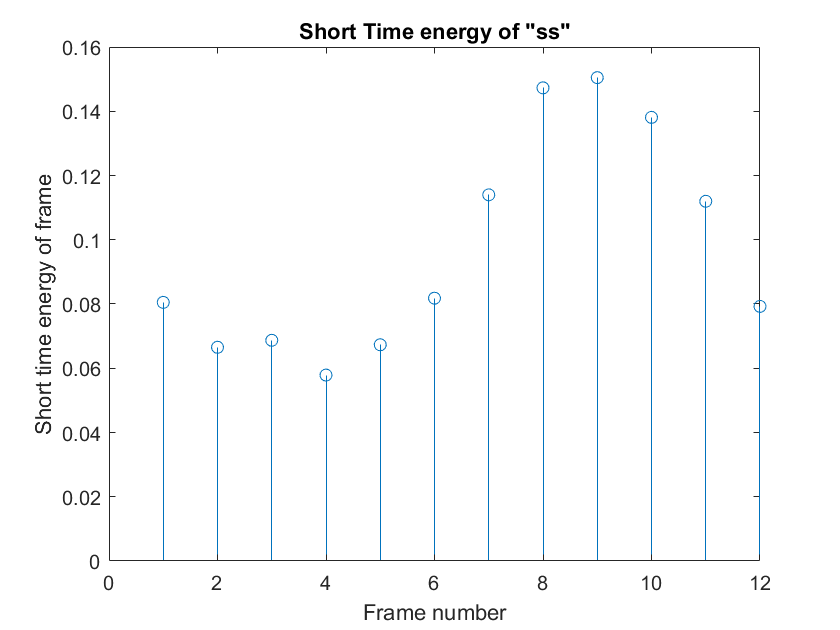

[no_of_frames_ss, E_ss] = calculate_energy(fs, frame_size, frame_shift, ss_sound);
plot_stem((1:no_of_frames_ss), E_ss, 'Short Time energy of "ss"', 'Frame number', 'Short time energy of frame');

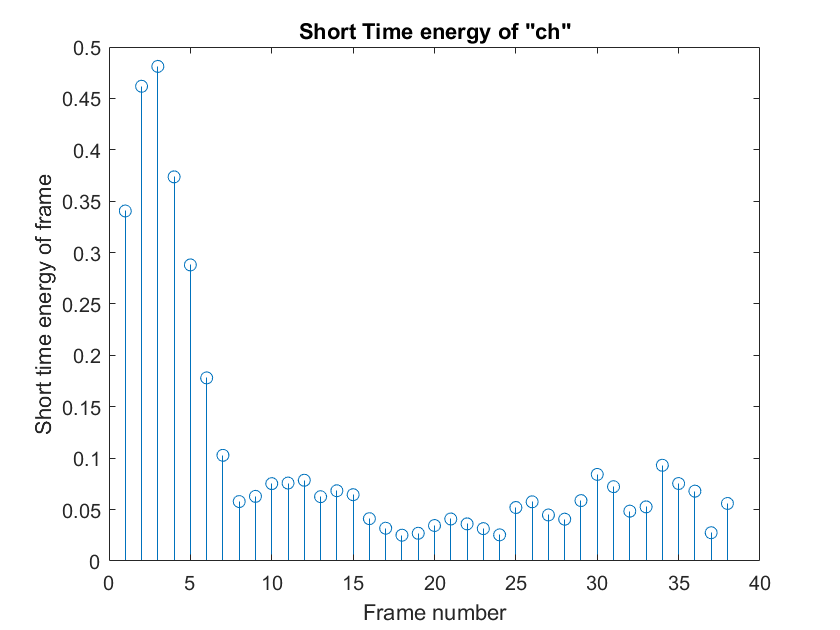

[no_of_frames_ch, E_ch] = calculate_energy(fs, frame_size, frame_shift, ch_sound);
plot_stem((1:no_of_frames_ch), E_ch, 'Short Time energy of "ch"', 'Frame number', 'Short time energy of frame');

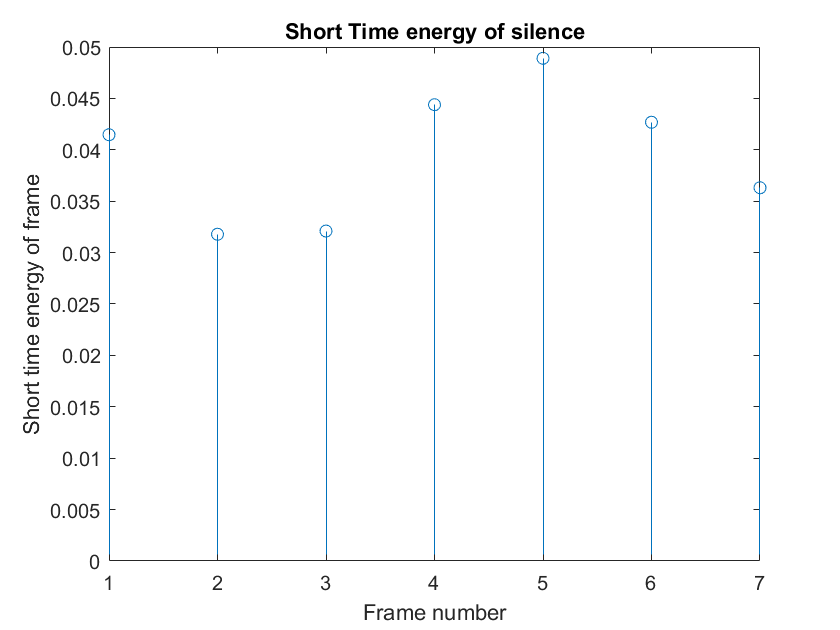


[no_of_frames_sil, E_sil] = calculate_energy(fs, frame_size, frame_shift, silence);
plot_stem((1:no_of_frames_sil), E_sil, 'Short Time energy of silence', 'Frame number', 'Short time energy of frame');

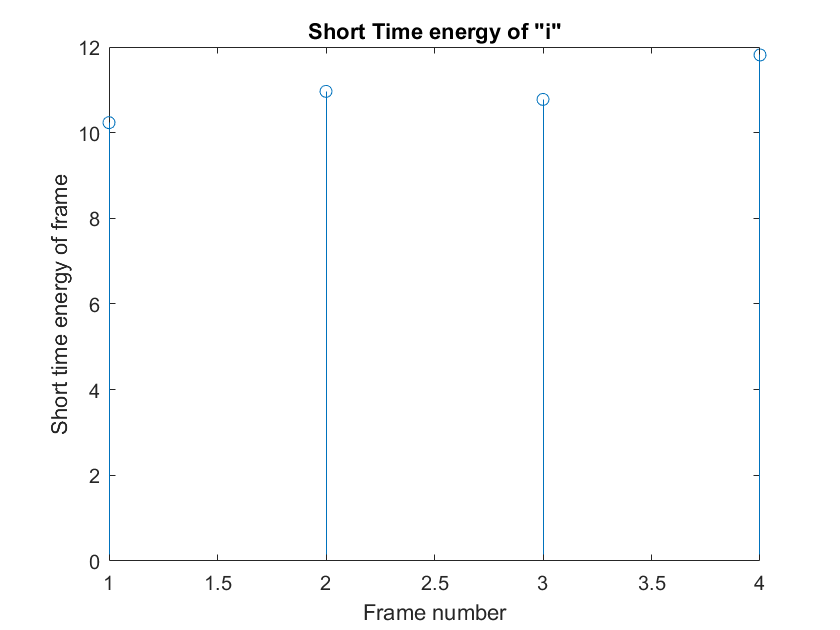


[no_of_frames_i, E_i] = calculate_energy(fs, frame_size, frame_shift, i_sound);
plot_stem((1:no_of_frames_i), E_i, 'Short Time energy of "i"', 'Frame number', 'Short time energy of frame');

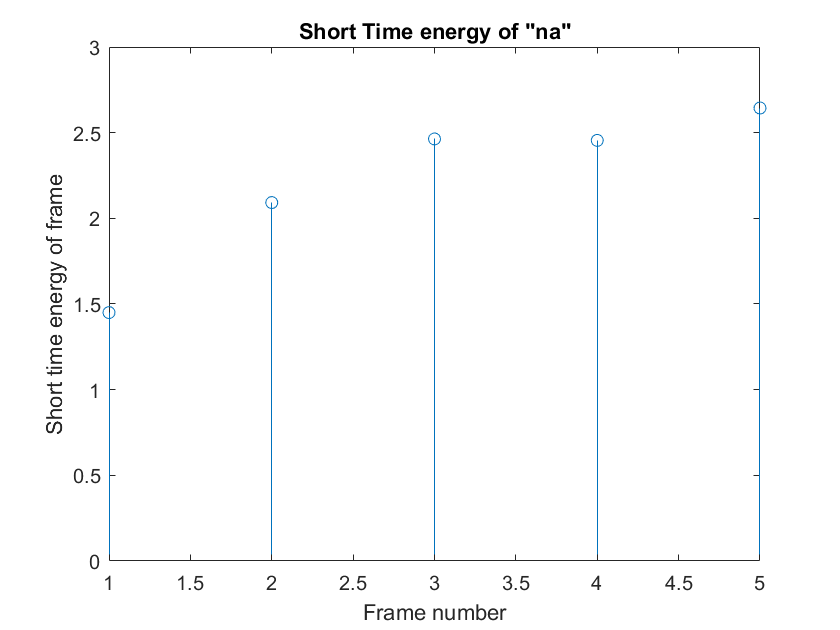


[no_of_frames_na, E_na] = calculate_energy(fs, frame_size, frame_shift, na_sound);
plot_stem((1:no_of_frames_na), E_na, 'Short Time energy of "na"', 'Frame number', 'Short time energy of frame');

### Comparison of the Short time energy plots for the 5 sounds:

###            Unvoiced Sounds

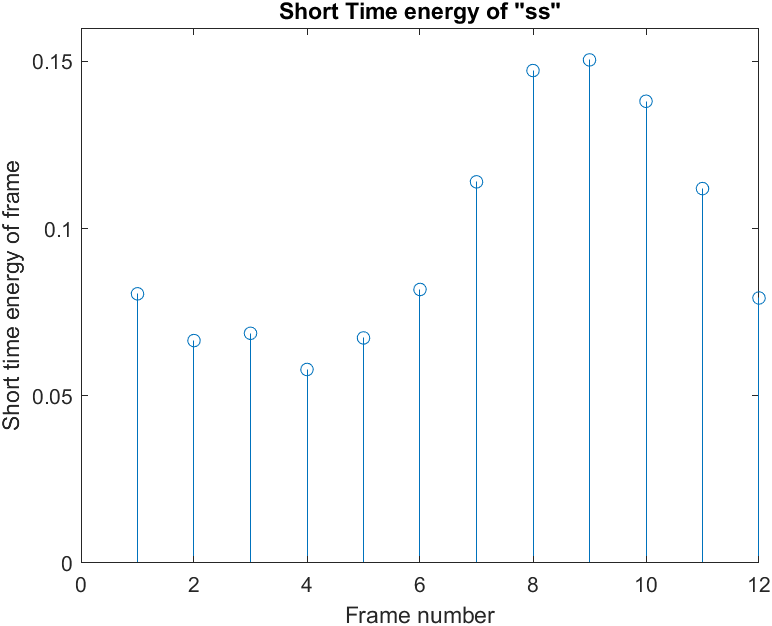                    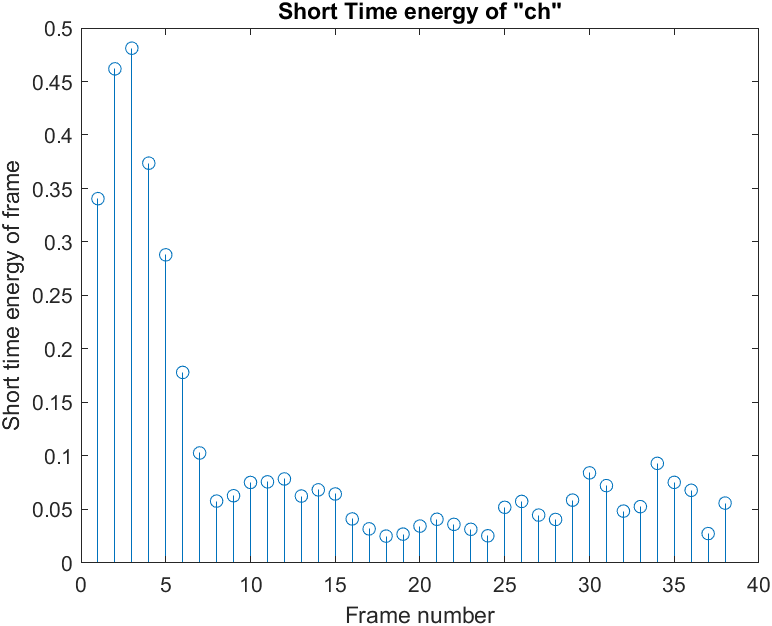

###             SIlence

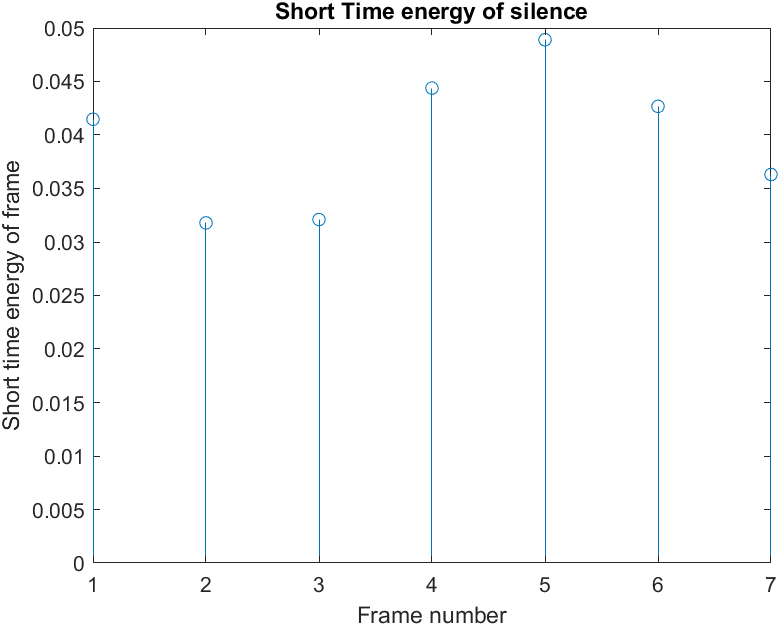

###         Voiced Sounds

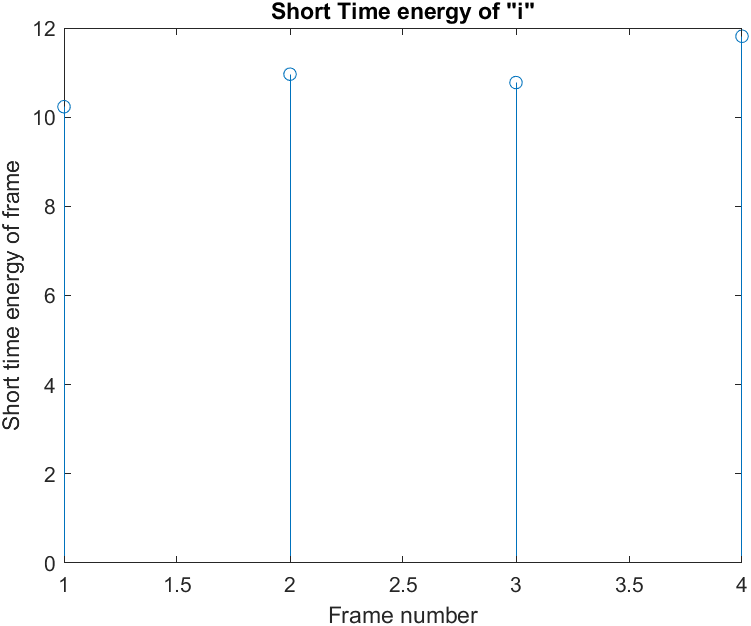                              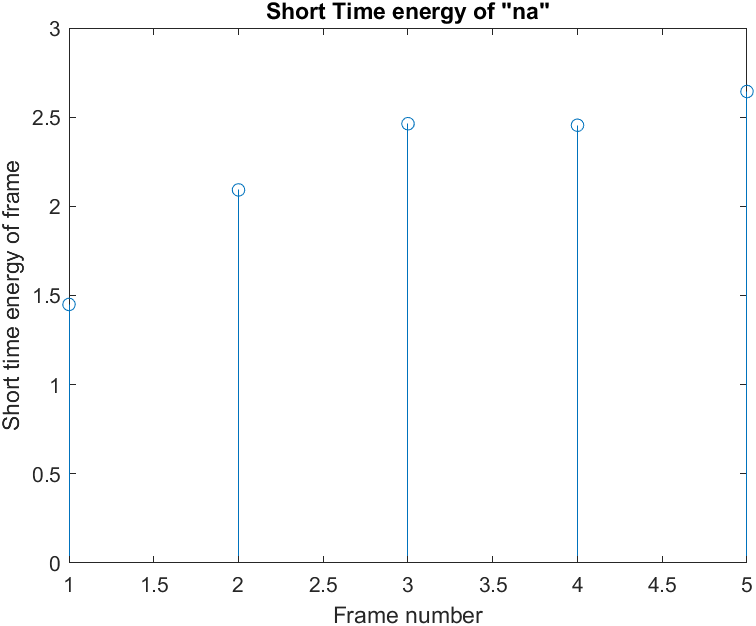

### Observations:

We see that for unvoiced sounds the short time energy is very less (ranging from 0.1 to 0.5) whereas for voiced it is significantly large (ranging from 2 to 12), For silence, the short time energy is significantly small (ranging from 0.03-0.05). Hence we can classify sounds as voiced, unvoiced or silence with the help of short time energy function. Short time energy is high for voiced sounds due to the smooth flow of periodic glottal vibrations, whereas for unvoiced there is some obstruction/constriction during air flow, hence energy will be lower.

#### ZCR Plotting

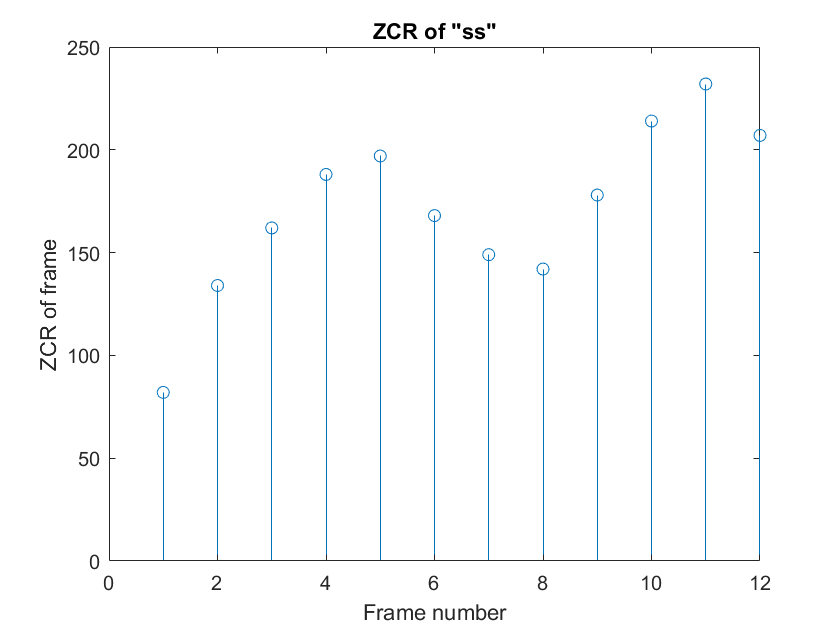

[no_of_frames_ss, zcr_ss] = calculate_zcr(fs, frame_size, frame_shift, ss_sound);
plot_stem((1:no_of_frames_ss), zcr_ss, 'ZCR of "ss"', 'Frame number', 'ZCR of frame');

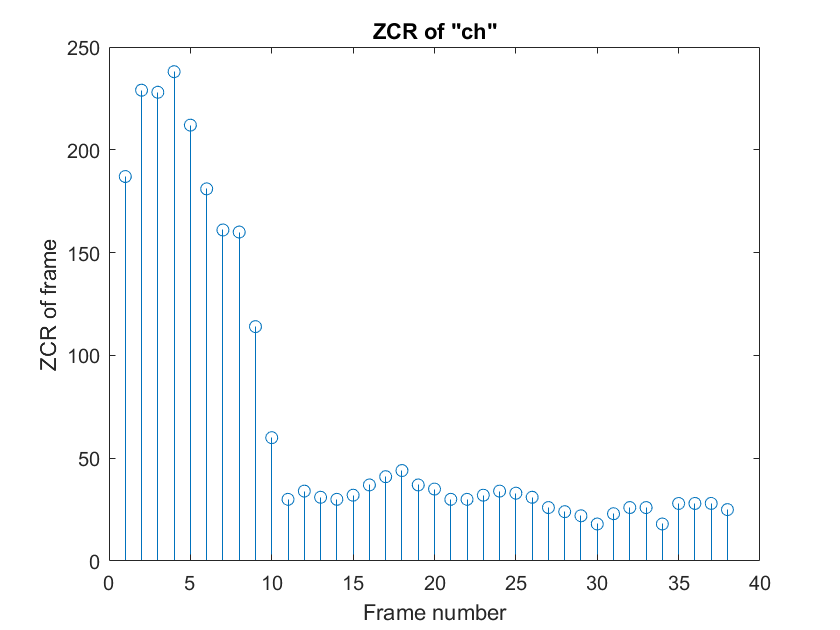


[no_of_frames_ch, zcr_ch] = calculate_zcr(fs, frame_size, frame_shift, ch_sound);
plot_stem((1:no_of_frames_ch), zcr_ch, 'ZCR of "ch"', 'Frame number', 'ZCR of frame');

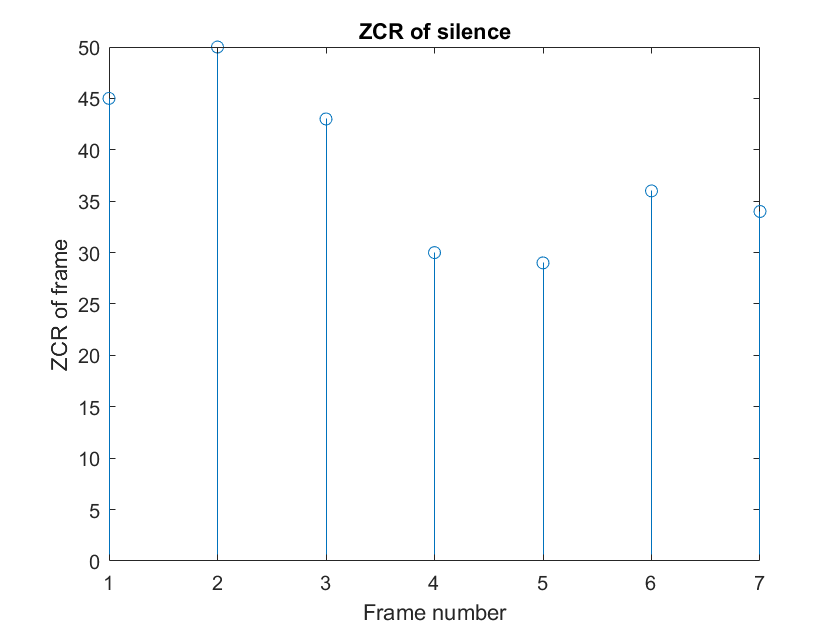


[no_of_frames_sil, zcr_sil] = calculate_zcr(fs, frame_size, frame_shift, silence);
plot_stem((1:no_of_frames_sil), zcr_sil, 'ZCR of silence', 'Frame number', 'ZCR of frame');

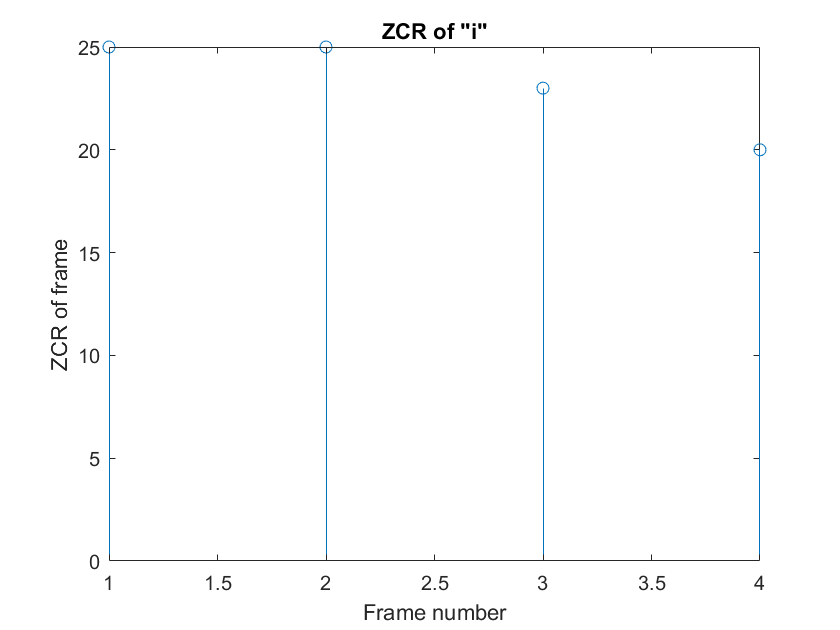


[no_of_frames_i, zcr_i] = calculate_zcr(fs, frame_size, frame_shift, i_sound);
plot_stem((1:no_of_frames_i), zcr_i, 'ZCR of "i"', 'Frame number', 'ZCR of frame');

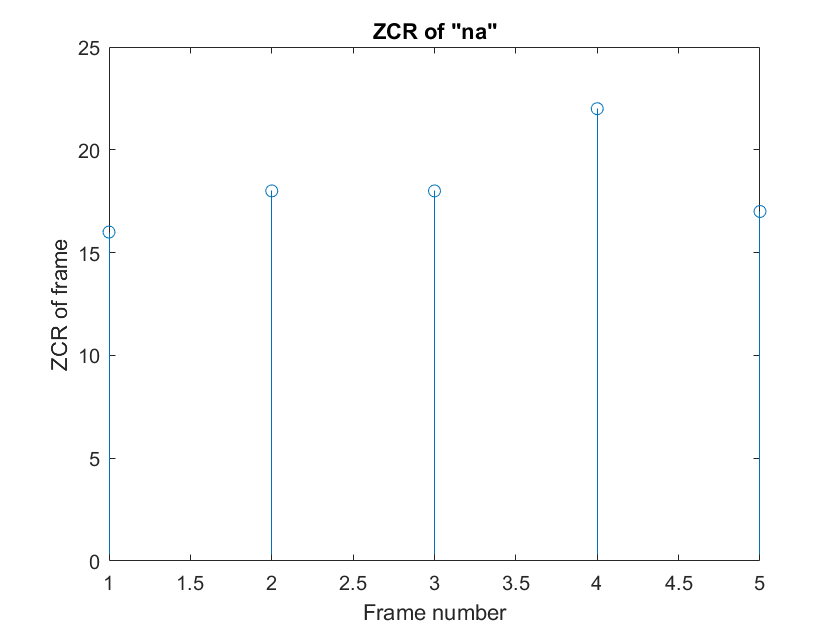


[no_of_frames_na, zcr_na] = calculate_zcr(fs, frame_size, frame_shift, na_sound);
plot_stem((1:no_of_frames_na), zcr_na, 'ZCR of "na"', 'Frame number', 'ZCR of frame');

### Comparison of the Short time energy plots for the 5 sounds:

###            Unvoiced Sounds

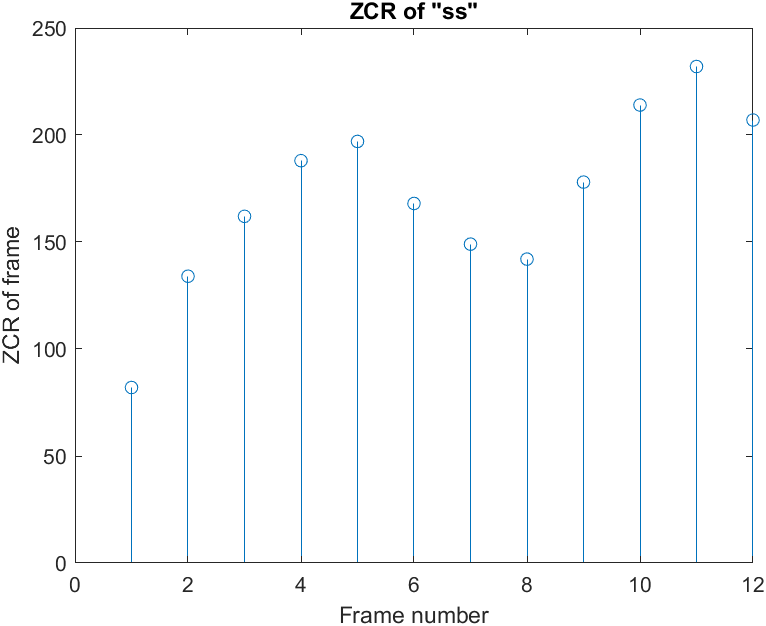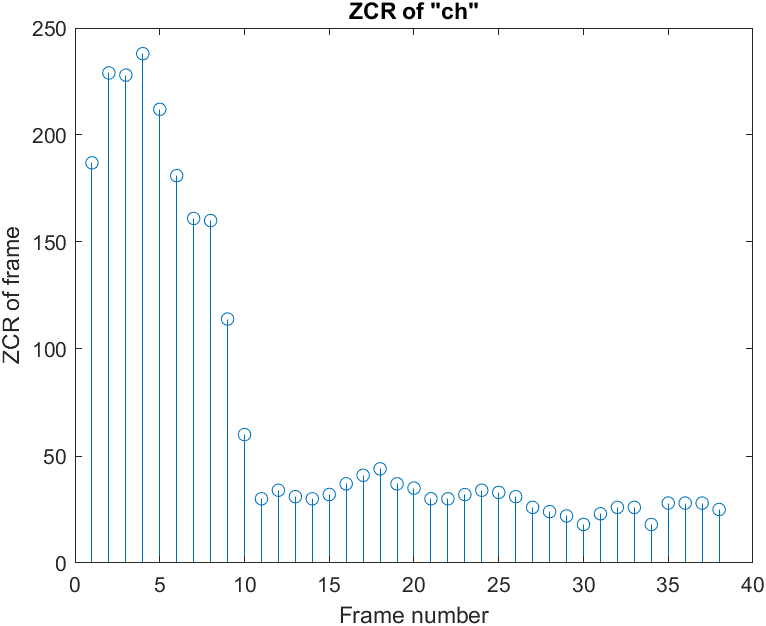

###            SIlence

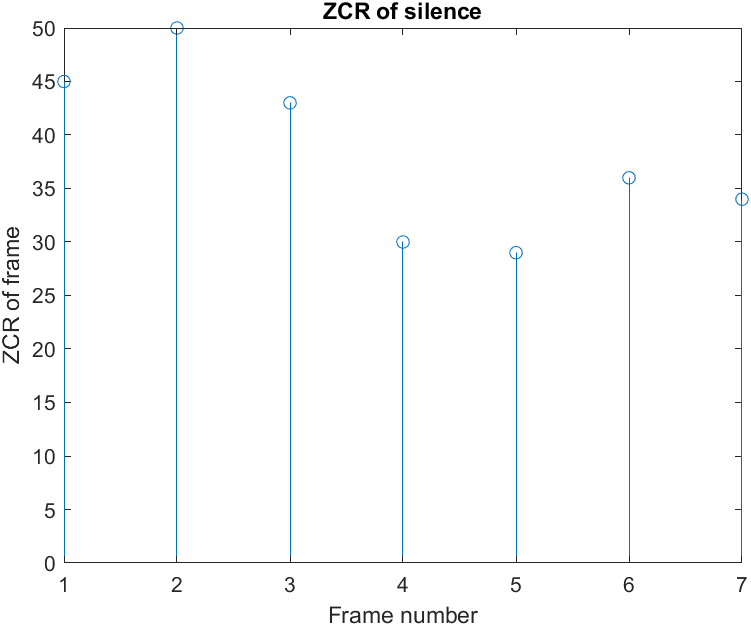

###            Voiced Sounds

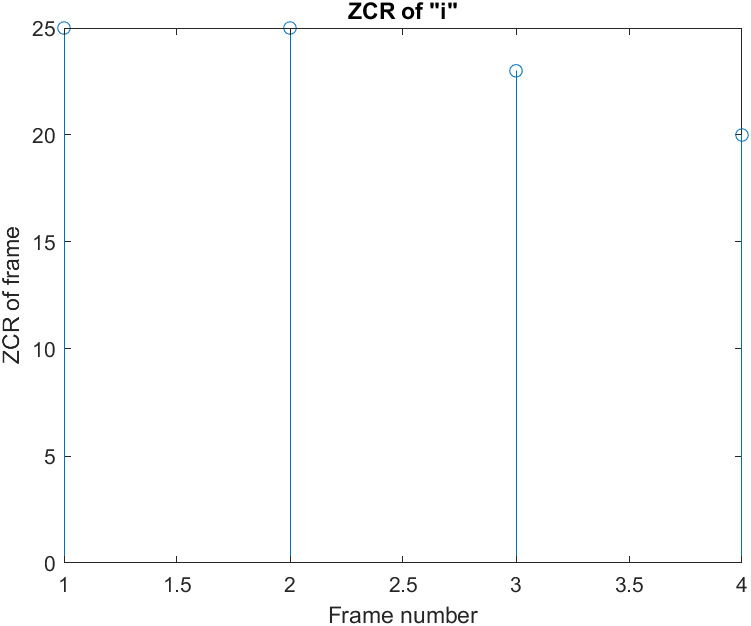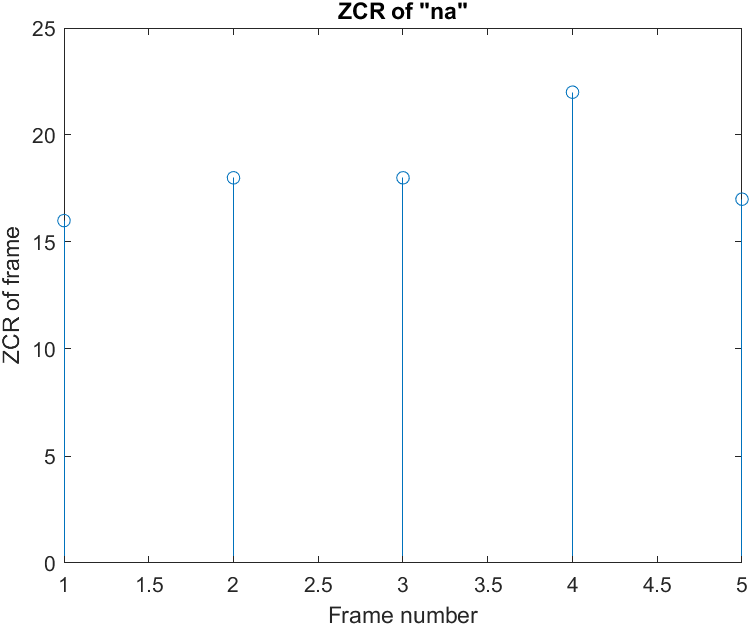

### Observations:

We see that for unvoiced sounds the ZCR is very high (ranging from 40 to 240) wherease for voiced it is significantly low (ranging from 16 to 25), For silence, the ZCR is greater than that for voiced but lesser than that for unvoiced (ranging from 30 - 50). Hence we can classify sounds as voiced, unvoiced or silence with the help of ZCR. ZCR is high for unvoiced sounds due to noisy nature of the speech, whereas for voiced there is no noise that can cause the speech signal to fluctuate and cross zero axis..

### D.

### Plot the magnitude spectrum (with magnitude in log scale) of the 4 speech sounds. Comment/explain how the visual inspection of the spectrum can be used to classify the sound as voiced or unvoiced. 

### Theory:

Plotting signal in time domain is not enough to analyse speech signals, by plotting magnitude spectrum in log scale we can do much better analysis. By using N-point FFT on the sound segments, we can see the frequency spectrum of each of these sounds.

### Procedure:

We first take different sound segments from original speech signal (25 msec segments), and then plot these sounds using N-point FFT with the help of my user defined function *plot_freq_spectrum(x, fs, title_name)* (defined at the end). This user defined function uses inbuilt *fft()* function and plots magnitude spectrum (in log scale) for each sound.

### Code and Plots:

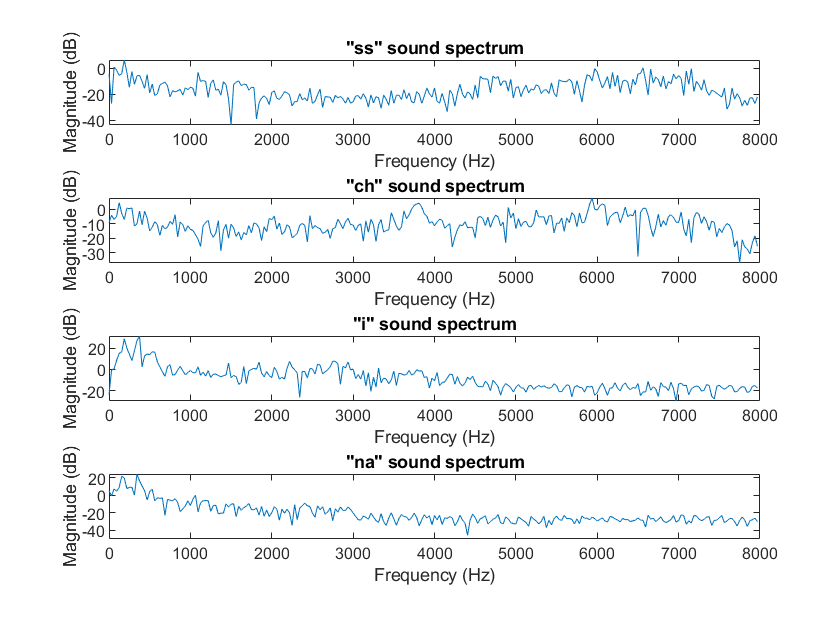

ss_sound = y(int64(0.085*fs):int64((0.085+0.025)*fs));
ch_sound = y(int64(0.64*fs):int64((0.64+0.025)*fs));
i_sound = y(int64(1.282*fs):int64((1.282+0.025)*fs));   % vowel
na_sound = y(int64(1.442*fs):int64((1.442+0.025)*fs));  % nasal

subplot(411);
plot_freq_spectrum(ss_sound, fs, '"ss" sound spectrum');

subplot(412);
plot_freq_spectrum(ch_sound, fs, '"ch" sound spectrum');

subplot(413);
plot_freq_spectrum(i_sound, fs, '"i" sound spectrum');

subplot(414);
plot_freq_spectrum(na_sound, fs, '"na" sound spectrum');

### Observations:

We see that for voiced speech, there is harmonic structure associated in the spectrum, whereas in unvoiced and silence, there is no such harmonic structure seen in the spectrums. This is due to the periodic nature of voiced sounds, hence pitch frequency and its harmonics are seen much more clearly.

### Function Definitions

function plot_time_signal(y, fs, title_name)  % PLOT TIME DOMAIN PLOT FOR ANY SIGNAL
    plot((0:length(y)-1)/fs,y);
    xlabel("Time");
    ylabel("Amplitude");
    title(title_name);
end

% PLOT FREQUENCY SPECTRUM FOR ANY SIGNAL
function plot_freq_spectrum(x, fs, title_name)
    N = length(x);
    n = pow2(nextpow2(N)); % Transforming the length so that the number of samples is a power of 2. 
    f = fs*[0: n-1]/n;
    X_mags = 20*log10(abs(fft(x, n)));
    N_2 = ceil(n/2);
    plot(f(1:N_2), (X_mags(1:N_2)));
    xlabel('Frequency (Hz)')
    ylabel('Magnitude (dB)');
    title(title_name);
end

% PLOT STEM PLOT FOR ANY SIGNAL
function plot_stem(x, y, title_name, x_label, y_label)
    stem(x,y);
    xlabel(x_label);
    ylabel(y_label);
    title(title_name);
end

% CALCULATING AUTO CORRELATION FUNCTION
function ACF = autocorr(no_of_samples, signal)
    N = no_of_samples;
    ACF = [];
    for i = 1:N 
        sum = 0;
        for j = 1:N-i
            sum = sum + signal(j)*signal(j+i);
        end
        ACF = [ACF sum];
    end
end

% CALCULATING SHORT TIME ENERGY FRAME BY FRAME FOR A GIVEN FRAME SIZE AND
% FRAME SHIFT FOR ANY SIGNAL 
function [no_of_frames, E] = calculate_energy(fs, frame_size, frame_shift, signal)
    no_of_frames = length(0:frame_shift:length(signal)/fs-frame_size);
    
    E = [];
    n = 0;
    for i = 1:no_of_frames
        x = signal((1+floor((n*frame_shift)*fs)):(floor((n*frame_shift + frame_size)*fs)));
        sum = 0;
        for j = 1:length(x)
            sum = sum + x(j)*x(j);
        end
        E = [E sum];
        n = n+1;
    end
end

% CALCULATING ZCR FRAME BY FRAME FOR A GIVEN FRAME SIZE AND
% FRAME SHIFT FOR ANY SIGNAL 
function [no_of_frames, zcr] = calculate_zcr(fs, frame_size, frame_shift, signal)
    no_of_frames = length(0:frame_shift:length(signal)/fs-frame_size);
    
    zcr = [];
    n = 0;
    
    for i = 1:no_of_frames
        x = signal((1+floor((n*frame_shift)*fs)):(floor((n*frame_shift + frame_size)*fs)));
        
        count = 0;
        
        for j = 2:length(x)
            if((x(j-1) >=0 && x(j) <0) || (x(j-1) < 0 && x(j) >= 0) )
                count = count + 1; 
            end
        end
        
        zcr = [zcr count];
        n = n+1;
    end
end


function pitch_f_ACF = getPitchACF(x)
 % ACF
    ACF = autocorr(length(x), x);
    threshold = 0.74; % threshold for a significant peak
    
    for i = 2 : length(ACF)-1
        if ACF(i) > ACF(i-1) && ACF(i) > ACF(i+1)
            if(ACF(i) > threshold)
                peak_ACF = i;
                break;
            end
        end
    end

    pitch_pd = peak_ACF - 1;
    pitch_f_ACF = (1/pitch_pd)*fs;    
end

function pitch_f_Cep = getPitchCep(x)
    % Cepstral
    % getting c_n i.e. cepstrum 
    cepst= ifft(log(abs(fftshift(fft(x)))));
    cepst= cepst_voiced(1:round(length(cepst_voiced)/2));
    Lc = 15;
    w_2 = zeros(1,length(cepst));
    w_2(Lc:length(cepst)) = 1;
    
    % high pass liftering
    high_liftered= cepst.*w_2';
    
    % pitch estimation
    xIndex = find(high_liftered== max(high_liftered), 1, 'first');
    pitch_pd = xIndex/fs;
    pitch_f_Cep = (1/pitch_pd);
end

function pitch_f_SIFT = getPitchSIFT(x)
    % SIFT
    ACF = autocorr(length(x), x);
    P = 13; % Order
    
    R = ACF(1:P); % R(0) to R(P-1)
    r = (ACF(2:(P+1)))'; % R(1) to R(P)
    
    R = toeplitz(R); % writing in form of toeplitz matrix
    L_coeffs = -(inv(R))*(r);
    
    LP_residual = conv(x, L_coeffs);
    ACF_LP = autocorr(length(LP_residual), LP_residual);
    
    [mag, k] = max(ACF_LP(2:end)); % ignoring the 1st index as it has highest peak
    pitch_pd = k+1;
    pitch_f_SIFT = (1/pitch_pd)*fs;
end



